%PID CONTROL DECENTRALIZADO
clc; close all; clear all;
 m1 = 0.75;
 m2 = 0.5;
 k1 = 100;
 k2 = 100;
 p1 = 80;
 p2 = 50;
A = [0 0 1 0;0 0 0 1;(-k1-k2)/m1 k2/m1 (-p1-p2)/m1 p2/m1; k2/m2 -k2/m2 p2/m2 -p2/m2 ]

A =          0         0    1.0000         0
         0         0         0    1.0000
 -266.6667  133.3333 -173.3333   66.6667
  200.0000 -200.0000  100.0000 -100.0000


B = [0 0; 0 0; 1/m1 0 ; 0 1/m2]

B =          0         0
         0         0
    1.3333         0
         0    2.0000


C = [eye(2), zeros(2)];
D = [zeros(2)];

% estabilidad
eig(A)

ans =  -224.4072
   -2.0432
   -1.2752
  -45.6077


Gss = ss(A,B,C,D)

Gss =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3  -266.7   133.3  -173.3   66.67
   x4     200    -200     100    -100
 
  B = 
          u1     u2
   x1      0      0
   x2      0      0
   x3  1.333      0
   x4      0      2
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


G = tf(Gss);
pole(G)

ans =  -224.4072
  -45.6077
   -2.0432
   -1.2752
 -224.4072
  -45.6077
   -2.0432
   -1.2752


s = tf('s');
C = tf(zeros(2));

C(1,1) = pidtune(G(1,1),'PID'); % se puede meter cualkier controlador
C(1,2) = 0;
C(2,1) = 0;
C(2,2) = pidtune(G(2,2),'PID'); % se piuede modificar con cuakier controlador

Glc = feedback(G*C,eye(2))

Glc =
 
  From input 1 to output...
                 182.1 s^8 + 6.918e04 s^7 + 7.443e06 s^6 + 2.534e08 s^5 + 2.004e09 s^4 + 7.289e09 s^3 + 1.414e10 s^2 + 1.425e10 s + 5.81e09
   1:  -----------------------------------------------------------------------------------------------------------------------------------------------
       s^10 + 550.7 s^9 + 9.911e04 s^8 + 6.532e06 s^7 + 1.681e08 s^6 + 1.429e09 s^5 + 6.262e09 s^4 + 1.567e10 s^3 + 2.26e10 s^2 + 1.764e10 s + 5.81e09
 
                       1.821e04 s^7 + 5.06e06 s^6 + 2.253e08 s^5 + 1.571e09 s^4 + 4.351e09 s^3 + 5.359e09 s^2 + 2.437e09 s + 8.219e-07
   2:  -----------------------------------------------------------------------------------------------------------------------------------------------
       s^10 + 550.7 s^9 + 9.911e04 s^8 + 6.532e06 s^7 + 1.681e08 s^6 + 1.429e09 s^5 + 6.262e09 s^4 + 1.567e10 s^3 + 2.26e10 s^2 + 1.764e10 s + 5.81e09
 
  From input 2 to output...
                 267 s^8 + 8.414e04 s^7 + 6.076e06 s^

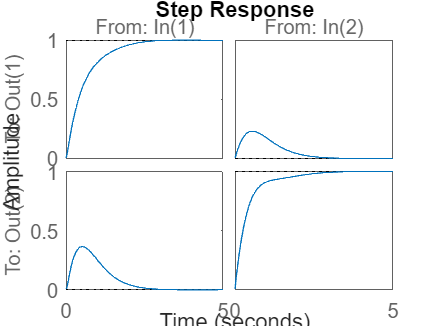

step(Glc)

**METODO RGA**

%Evalua si es directo o inverso, para ver en cuales poner el controlador
Gdc = dcgain(G); %Evalua en cero
%Gdc = eva
RGA = Gdc.*(Gdc')^-1

RGA =     2.0000   -1.0000
   -1.0000    2.0000


% Ejercicio 1) Control desentralizado

clc; close all; clear all;
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


G = [1/(4*s+1) 2.5/(15*s+1); 4/(20*s+1) 1/(5*s+1)]

G =
 
  From input 1 to output...
          1
   1:  -------
       4 s + 1
 
          4
   2:  --------
       20 s + 1
 
  From input 2 to output...
         2.5
   1:  --------
       15 s + 1
 
          1
   2:  -------
       5 s + 1
 
Continuous-time transfer function.
Model Properties


Gss = ss(G)

Gss =
 
  A = 
             x1        x2        x3        x4
   x1     -0.25         0         0         0
   x2         0     -0.05         0         0
   x3         0         0  -0.06667         0
   x4         0         0         0      -0.2
 
  B = 
        u1   u2
   x1  0.5    0
   x2  0.5    0
   x3    0  0.5
   x4    0  0.5
 
  C = 
           x1      x2      x3      x4
   y1     0.5       0  0.3333       0
   y2       0     0.4       0     0.4
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


Gs = tf(Gss)

Gs =
 
  From input 1 to output...
         0.25
   1:  --------
       s + 0.25
 
         0.2
   2:  --------
       s + 0.05
 
  From input 2 to output...
         0.1667
   1:  -----------
       s + 0.06667
 
         0.2
   2:  -------
       s + 0.2
 
Continuous-time transfer function.
Model Properties



Gdc = dcgain(G); %Evalua en cero
RGA = Gdc.*(Gdc')^-1

RGA =    -0.1111    1.1111
    1.1111   -0.1111


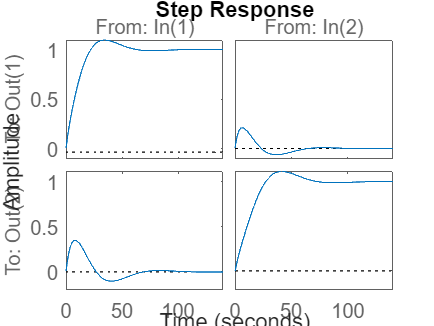


C = tf(zeros(2));
C(1,1) = 0;
C(1,2) = pidtune(Gs(2,1),'PID'); % Se pone invertido (1,2) --> (2,1)
C(2,1) = pidtune(Gs(1,2),'PID'); % Se pone invertido (2,1) --> (1,2)
C(2,2) = 0; 

Glc = feedback(Gs*C,eye(2));
step(Glc)

% Ejercicio 2) Control DeCentralizado 
clc; clear all; close all;
r1 = 0.5;
r2 = 1;
a1 = 0.25;
a2 = 0.2;

A = [-1/(a1*r1) 1/(a1*r1); 1/(a2*r1) (-1/r1-1/r2)/a2 ]

A =     -8     8
    10   -15


B = [1/a1 0; 0 -1/a2]

B =      4     0
     0    -5


C = eye(2);
D = zeros(2);


Gss = ss(A,B,C,D);
Gs = tf(Gss)

Gs =
 
  From input 1 to output...
          4 s + 60
   1:  ---------------
       s^2 + 23 s + 40
 
             40
   2:  ---------------
       s^2 + 23 s + 40
 
  From input 2 to output...
             -40
   1:  ---------------
       s^2 + 23 s + 40
 
          -5 s - 40
   2:  ---------------
       s^2 + 23 s + 40
 
Continuous-time transfer function.
Model Properties



% Gdc = dcgain(G); %Evalua en cero
% RGA = Gdc.*(Gdc')^-1
% 
% C = tf(zeros(2));
% C(1,1) = pidtune(Gs(1,1),'PID'); % Se pone invertido (1,2) --> (2,1)
% C(2,2) = pidtune(Gs(2,2),'PID'); % Se pone invertido (2,1) --> (1,2)

C = Control_RGA_descentr(Gs)

Gdc =     1.5000   -1.0000
    1.0000   -1.0000


RGA =     3.0000   -2.0000
   -2.0000    3.0000


pairs_sorted =     3.0000    2.0000    2.0000
    3.0000    1.0000    1.0000
   -2.0000    2.0000    1.0000
   -2.0000    1.0000    2.0000


pairs =      2     2
     1     1
     2     1
     1     2


nn =      2     2
     1     1


Cs =
 
  From input 1 to output...
   1:  0
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       -1.146 s - 7.066
   2:  ----------------
              s
 
Continuous-time transfer function.
Model Properties

Cs =
 
  From input 1 to output...
       0.8868 s + 3.475
   1:  ----------------
              s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       -1.146 s - 7.066
   2:  

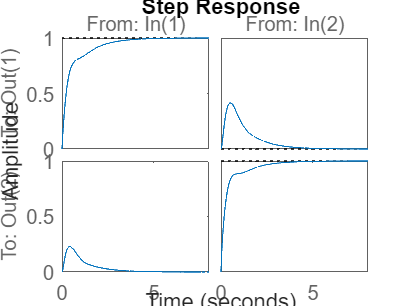

Glc = feedback(Gs*C,eye(2));
step(Glc)

% Ejercicio 3) MATRIZ 3X3 a mas ++++ 
% ......
clc; clear all; close all;
A = [-3.32 3.32 0;
    3.32 -3.32-2.67 2.67;
    0 2.67 -2.67-1]

A =    -3.3200    3.3200         0
    3.3200   -5.9900    2.6700
         0    2.6700   -3.6700


B = [1 20 0; 20 1 0; 0 0 1]

B =      1    20     0
    20     1     0
     0     0     1


C = eye(3)

C =      1     0     0
     0     1     0
     0     0     1


D = zeros(3)

D =      0     0     0
     0     0     0
     0     0     0



Gss = ss(A,B,C,D);
Gs = tf(Gss)

Gs =
 
  From input 1 to output...
            s^2 + 76.06 s + 258.5
   1:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
           20 s^2 + 143.1 s + 255.9
   2:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
                53.4 s + 186.2
   3:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
  From input 2 to output...
           20 s^2 + 196.5 s + 309.3
   1:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
            s^2 + 73.39 s + 255.9
   2:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
                2.67 s + 186.2
   3:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
  From input 3 to output...
                    8.864
   1:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
                2.67 s + 8.864
   2:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.


Gdc = dcgain(Gs); %Evalua en cero

RGA =    -5.0964    6.0964   -0.0000
    8.9070   -5.2370   -2.6700
   -2.8105    0.1405    3.6700


RGA = Gdc.*(Gdc')^-1

% G(a,b) <---- estas cordenadas e consigue en RGA
% C(b,a) ---> G(a,b)
Cs = Control_RGA_descentr(Gs)

Gdc =    29.1664   34.8893    1.0000
   28.8652   28.8652    1.0000
   21.0000   21.0000    1.0000


RGA =    -5.0964    6.0964   -0.0000
    8.9070   -5.2370   -2.6700
   -2.8105    0.1405    3.6700


pairs_sorted =     8.9070    2.0000    1.0000
    6.0964    1.0000    2.0000
    3.6700    3.0000    3.0000
    0.1405    3.0000    2.0000
   -0.0000    1.0000    3.0000
   -2.6700    2.0000    3.0000
   -2.8105    3.0000    1.0000
   -5.0964    1.0000    1.0000
   -5.2370    2.0000    2.0000


pairs =      2     1
     1     2
     3     3
     3     2
     1     3
     2     3
     3     1
     1     1
     2     2


nn =      2     1
     1     2
     3     3


Cs =
 
  From input 1 to output...
   1:  0
 
   2:  0
 
   3:  0
 
  From input 2 to output...
       0.04126 s + 0.02854
   1:  -------------------
                s
 
   2:  0
 
   3:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
   3:  0
 
Continuous-time transfer function.
Model Properties

Cs =
 
  From input 1 to output...
   1:  0
 
       0.03215 s + 0.02381
   2:  -----------

% Cs = tf(zeros(3));
% Cs(1,2) = pidtune(Gs(2,1),'PID');
% Cs(2,1) = pidtune(Gs(1,2),'PID'); 
% Cs(3,3) = pidtune(Gs(3,3),'PID'); 


Glc = feedback(Gs*Cs,eye(3));
%step(Glc)


%CONTROL LQR DESCENTRALIZADO.
clc; clear all; close all;
A = [-3.32 3.32 0;
    3.32 -3.32-2.67 2.67;
    0 2.67 -2.67-1]

A =    -3.3200    3.3200         0
    3.3200   -5.9900    2.6700
         0    2.6700   -3.6700


B = [1 20 0; 20 1 0; 0 0 1]

B =      1    20     0
    20     1     0
     0     0     1


C = eye(3)

C =      1     0     0
     0     1     0
     0     0     1


D = zeros(3)

D =      0     0     0
     0     0     0
     0     0     0



Gss = ss(A,B,C,D);
Gs = tf(Gss)

Gs =
 
  From input 1 to output...
            s^2 + 76.06 s + 258.5
   1:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
           20 s^2 + 143.1 s + 255.9
   2:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
                53.4 s + 186.2
   3:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
  From input 2 to output...
           20 s^2 + 196.5 s + 309.3
   1:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
            s^2 + 73.39 s + 255.9
   2:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
                2.67 s + 186.2
   3:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
  From input 3 to output...
                    8.864
   1:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
                2.67 s + 8.864
   2:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.


% G(a,b) <---- estas cordenadas e consigue en RGA
% C(b,a) ---> G(a,b)
pares = Pares_Desc(Gs)

pairs_sorted =     8.9070    2.0000    1.0000
    6.0964    1.0000    2.0000
    3.6700    3.0000    3.0000
    0.1405    3.0000    2.0000
   -0.0000    1.0000    3.0000
   -2.6700    2.0000    3.0000
   -2.8105    3.0000    1.0000
   -5.0964    1.0000    1.0000
   -5.2370    2.0000    2.0000


pairs =      2     1
     1     2
     3     3
     3     2
     1     3
     2     3
     3     1
     1     1
     2     2


pares =      2     1
     1     2
     3     3


% Cs = tf(zeros(3));
% Cs(1,2) = pidtune(Gs(2,1),'PID');
% Cs(2,1) = pidtune(Gs(1,2),'PID'); 
% Cs(3,3) = pidtune(Gs(3,3),'PID'); 


%Glc = feedback(Gs*Cs,eye(3));
%step(Glc)



function Cs = Control_RGA_descentr(G)
Gdc = dcgain(G)
RGA=Gdc.*(Gdc')^-1 
[nRows, nCols] = size(RGA);
pairs = [];
for i = 1:nRows
    for j = 1:nCols
        pairs = [pairs; RGA(i, j), i, j]; 
    end
end

pairs_sorted = sortrows(pairs,'descend')
pairs= pairs_sorted(1:end,2:3) 
selected_pairs = [];
rows_used = [];
cols_used = [];
for i = 1:size(pairs, 1)
    row = pairs(i, 1);
    col = pairs(i, 2);
    
    if ~ismember(row, rows_used) && ~ismember(col, cols_used)
        selected_pairs = [selected_pairs; row, col];
        rows_used = [rows_used, row];
        cols_used = [cols_used, col];
    end
    
    if size(selected_pairs, 1) == nRows
        break;
    end
end
nn = selected_pairs
Cs = tf(zeros(length(selected_pairs)));
for i = 1:length(selected_pairs)
    
    %Configura el controlador que deseas
    %---------------------------------------

    Cs(nn(i,2),nn(i,1)) = pidtune(G(nn(i,1),nn(i,2)),'PID')

    %---------------------------------------
end
end

function Pares = Pares_Desc(G)
Gdc = dcgain(G);
RGA=Gdc.*(Gdc')^-1 ;
[nRows, nCols] = size(RGA);
pairs = [];
for i = 1:nRows
    for j = 1:nCols
        pairs = [pairs; RGA(i, j), i, j]; 
    end
end

pairs_sorted = sortrows(pairs,'descend')
pairs= pairs_sorted(1:end,2:3) 
selected_pairs = [];
rows_used = [];
cols_used = [];
for i = 1:size(pairs, 1)
    row = pairs(i, 1);
    col = pairs(i, 2);
    
    if ~ismember(row, rows_used) && ~ismember(col, cols_used)
        selected_pairs = [selected_pairs; row, col];
        rows_used = [rows_used, row];
        cols_used = [cols_used, col];
    end
    
    if size(selected_pairs, 1) == nRows
        break;
    end
end
Pares = selected_pairs;
end